# CSV to png and workspace

**Csv name format - <name1>_<name2>_<name3>.csv ****no - '( { /...'**

CSV to workspace: will add to workspace vectors <type>_<element>_<mesurmant parameter> :type = dB_mag or lin_mag, elemant = <name1>, mesurmant = <name2>

% Set the directory containing the CSV files
csv_directory = '/Users/ohadformanair/Documents/Git/AML/LAB_3p4/lab3&4_microwave_lab/CSV_data';

% Set the directory for saving the plots
save_directory = '/Users/ohadformanair/Documents/Git/AML/LAB_3p4/lab3&4_microwave_lab/csv_plots';

%Set stat result directory
stat_directory = '/Users/ohadformanair/Documents/Git/AML/LAB_3p4/Stat_results';

stat_directory = '/Users/ohadformanair/Documents/Git/AML/LAB_3p4/Stat_results'

% Initialize the output variables
linear_magnitude_data = [];
dB_magnitude_data = [];
phase_data = [];

% Initialize table for magnitude statistics
mag_stats = table();

% Loop over each file in the directory
filelist = dir(fullfile(csv_directory, '*.csv'));
for i = 1:length(filelist)
    % Extract the filename components
    [~, filename, ~] = fileparts(filelist(i).name);
    name_parts = split(filename, '_');
    name1 = name_parts{1};
    name2 = name_parts{2};

    % Load the data from the current file
    data = readmatrix(fullfile(csv_directory, filelist(i).name), 'HeaderLines', 3);

    % Extract the frequency and formatted data columns
    frequency = data(:, 1); % Don't normalize frequency
    formatted_data = data(:, 2);

    % Calculate the magnitude data in linear and dB units
    if strcmp(name_parts(end), 'MAG')
        linear_magnitude = formatted_data;
        dB_magnitude = 20*log10(formatted_data);
        linear_phase = [];
        phase = [];
        
        % Calculate statistics and add to table
        mag_mean = mean(linear_magnitude);
        mag_median = median(linear_magnitude);
        mag_std = std(linear_magnitude);
        mag_min = min(linear_magnitude);
        mag_max = max(linear_magnitude);
        mag_stats = [mag_stats; table({name1}, {name2}, mag_mean, mag_median, mag_std, mag_min, mag_max)];
        
    elseif strcmp(name_parts(end), 'PHASE')
        linear_magnitude = [];
        dB_magnitude = [];
        linear_phase = formatted_data;
        phase = formatted_data;
    else
        % Invalid name3 value, skip this file
        continue;
    end

    % Append the data for this file to the output variables
    linear_magnitude_data = [linear_magnitude_data; linear_magnitude];
    dB_magnitude_data = [dB_magnitude_data; dB_magnitude];
    phase_data = [phase_data; phase];

    % Create variables in the workspace for the frequency and magnitude data
    freq_varname = ['freq_' name1 '_' name2];
    assignin('base', freq_varname, frequency);
    if ~isempty(linear_magnitude)
        lin_mag_varname = ['lin_mag_' name1 '_' name2];
        assignin('base', lin_mag_varname, linear_magnitude);
    end
    if ~isempty(dB_magnitude)
        dB_mag_varname = ['dB_mag_' name1 '_' name2];
        assignin('base', dB_mag_varname, dB_magnitude);
    end

    % Display the progress
    fprintf('Processed file %d of %d: %s\n', i, length(filelist), filelist(i).name);
end

Processed file 1 of 44: ATTENUATOR10dB_S11_MAG.CSV
Processed file 2 of 44: ATTENUATOR10dB_S11_PHASE.CSV
Processed file 3 of 44: ATTENUATOR10dB_S21_MAG.CSV
Processed file 4 of 44: ATTENUATOR10dB_S21_PHASE.CSV
Processed file 5 of 44: ATTENUATOR10dB_S22_MAG.CSV
Processed file 6 of 44: ATTENUATOR10dB_S22_PHASE.CSV
Processed file 7 of 44: CIRCULATOR_S11_MAG.CSV
Processed file 8 of 44: CIRCULATOR_S11_PHASE.CSV
Processed file 9 of 44: CIRCULATOR_S13_MAG.CSV
Processed file 10 of 44: CIRCULATOR_S13_PHASE.CSV
Processed file 11 of 44: CIRCULATOR_S22_MAG.CSV
Processed file 12 of 44: CIRCULATOR_S22_PHASE.CSV
Processed file 13 of 44: CIRCULATOR_S23_MAG.CSV
Processed file 14 of 44: CIRCULATOR_S23_PHASE.CSV
Processed file 15 of 44: CIRCULATOR_S31_MAG.CSV
Processed file 16 of 44: CIRCULATOR_S31_PHASE.CSV
Processed file 17 of 44: CIRCULATOR_S32_MAG.CSV
Processed file 18 of 44: CIRCULATOR_S32_PHASE.CSV
Processed file 19 of 44: CIRCULATOR_S33_MAG.CSV
Processed file 20 of 44: CIRCULATOR_S33_PHASE.CSV
Proce


% Assign the output variables to the workspace
assignin('base', 'linear_magnitude_data', linear_magnitude_data);
assignin('base', 'dB_magnitude_data', dB_magnitude_data);
assignin('base', 'phase_data', phase_data);

% Display the magnitude statistics table
disp(mag_stats);

           Var1            Var2      mag_mean     mag_median     mag_std      mag_min      mag_max 
    __________________    _______    _________    __________    _________    __________    ________

    {'ATTENUATOR10dB'}    {'S11'}      0.16397      0.17282      0.035995      0.087018     0.22521
    {'ATTENUATOR10dB'}    {'S21'}      0.31421      0.31912      0.017231       0.27307     0.34011
    {'ATTENUATOR10dB'}    {'S22'}     0.093437     0.088995      0.029913      0.043255     0.16793
    {'CIRCULATOR'    }    {'S11'}      0.49783      0.51505       0.14108       0.28723     0.68689
    {'CIRCULATOR'    }    {'S13'}      0.76035      0.75967      0.069075       0.61367     0.90136
    {'CIRCULATOR'    }    {'S22'}      0.55653      0.59575  

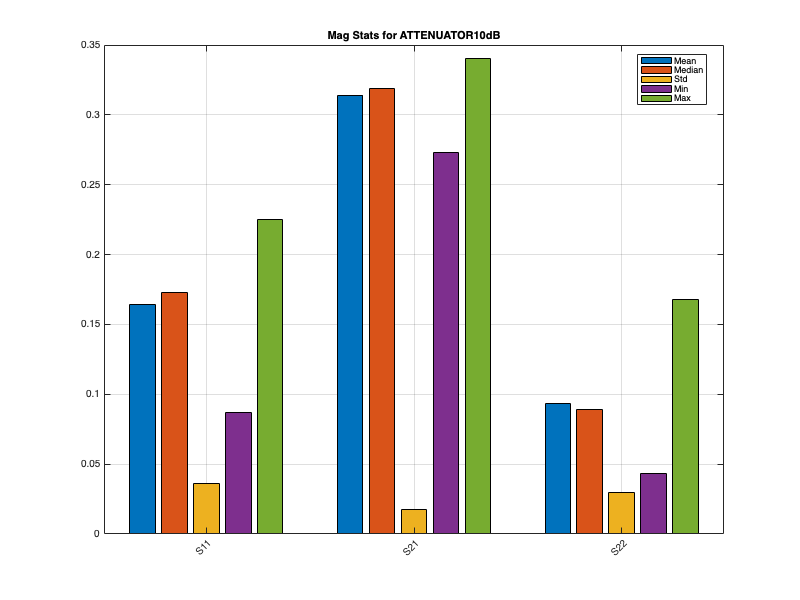

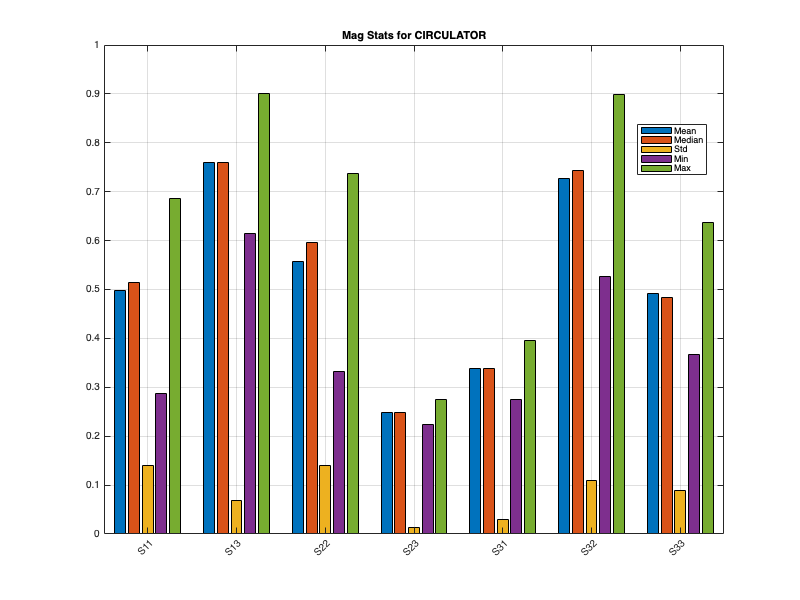

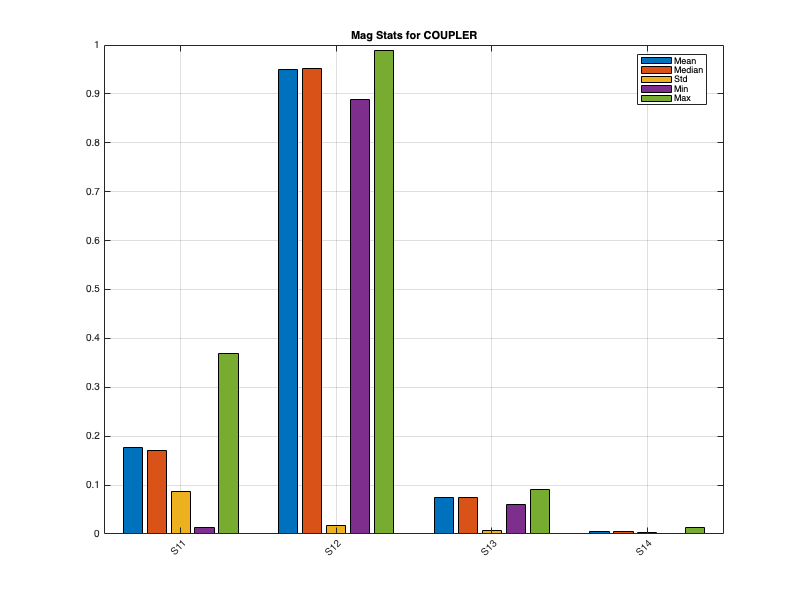

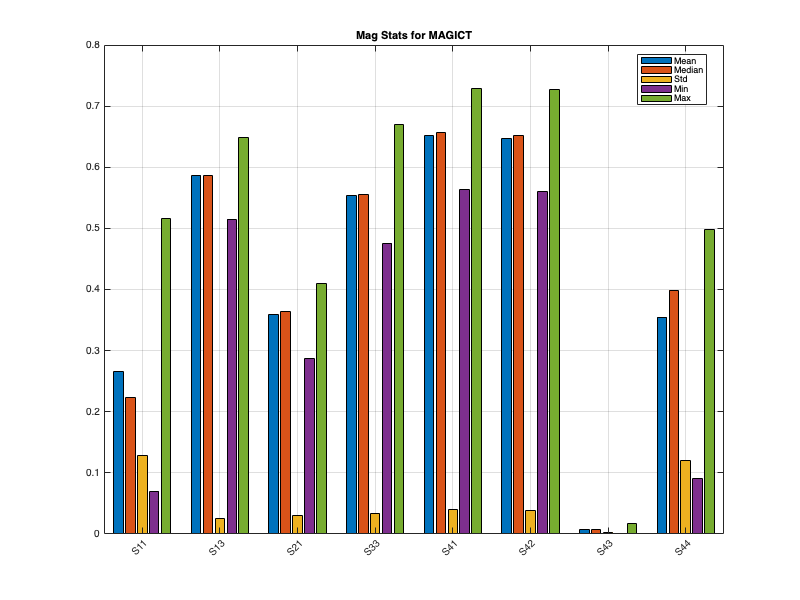

% Get unique values of Var1
Var1_vals = unique(mag_stats.Var1);

% Define figure width and height
fig_width = 800;
fig_height = 600;

% Loop over each unique value of Var1
for i = 1:length(Var1_vals)
    
    % Subset the table to only include rows with the current Var1 value
    subset = mag_stats(strcmp(mag_stats.Var1, Var1_vals{i}),:);
    
    % Get unique values of Var2 for this subset
    Var2_vals = unique(subset.Var2);
    
    % Initialize empty arrays for the statistics
    mag_mean = [];
    mag_median = [];
    mag_std = [];
    mag_min = [];
    mag_max = [];
    
    % Loop over each unique value of Var2 for this subset
    for j = 1:length(Var2_vals)
        
        % Subset the table to only include rows with the current Var1 and Var2 values
        subsubset = subset(strcmp(subset.Var2, Var2_vals{j}),:);
        
        % Check if each statistic is available for this subset
        if ~any(ismissing(subsubset.mag_mean))
            mag_mean(j) = subsubset.mag_mean;
        end
        if ~any(ismissing(subsubset.mag_median))
            mag_median(j) = subsubset.mag_median;
        end
        if ~any(ismissing(subsubset.mag_std))
            mag_std(j) = subsubset.mag_std;
        end
        if ~any(ismissing(subsubset.mag_min))
            mag_min(j) = subsubset.mag_min;
        end
        if ~any(ismissing(subsubset.mag_max))
            mag_max(j) = subsubset.mag_max;
        end
    end
    
    % Create new figure with specified size
    fig = figure('Position', [0, 0, fig_width, fig_height]);
    
    % Plot the statistics for this Var1 value
    bar([mag_mean' mag_median' mag_std' mag_min' mag_max'])
    xticklabels(Var2_vals)
    xtickangle(45)
    legend({'Mean','Median','Std','Min','Max'},'Location','Best')
    title(sprintf('Mag Stats for %s', Var1_vals{i}))
    grid on
    
    % Save the figure as a PNG file
    filename = fullfile(stat_directory, sprintf('mag_stats_%s.png', Var1_vals{i}));
    saveas(fig, filename);
    
end


% Save the table as a CSV file
filename = fullfile(stat_directory, 'mag_stats.csv');
writetable(mag_stats, filename);


**the plot title will be: <name1>: <name2> <name3>**

**the y axis will be: Phase(deg) if <name3> is PHASE, if MAG it will be : Magnitude (unit less)**

**the x axis is frequency.**

**set in script:**

**csv_directory = 'path/to/csv/files'**

**plot_directory = 'path/to/save/plots'**

**plot_mag_dB = (true for dB,  false for linear)**

% Set smoothing options
smoothing_enabled = false;  % Set to true to enable smoothing
smoothing_window_size = 1; % Size of the smoothing window (odd number)
% Set plot type options
is_bode_plot = true; % Set to true for Bode plot, false for linear magnitude plot

% Get a list of all CSV files in the directory
filelist = dir(fullfile(csv_directory, '*.csv'));

% Loop over each file in the directory
for i = 1:length(filelist)
    % Extract the filename components
    [~, filename, ~] = fileparts(filelist(i).name);
    name_parts = strsplit(filename, '_');
    name1 = name_parts{1};
    name2 = name_parts{2};
    name3 = name_parts{3};

    % Load the data from the current file
    data = readmatrix(fullfile(csv_directory, filelist(i).name), 'HeaderLines', 3);

    % Extract the frequency and formatted data columns
    frequency_data = data(:, 1);
    formatted_data = data(:, 2);

    % Smooth the data if enabled
    if smoothing_enabled
        smoothed_data = smooth(formatted_data, smoothing_window_size);
    else
        smoothed_data = formatted_data;
    end

    % Plot the magnitude and phase data in a Bode or linear plot
    if strcmp(name3, 'MAG')
        mag_data = smoothed_data;
        % Find the corresponding phase file
        phase_filename = fullfile(csv_directory, [name1 '_' name2 '_PHASE.csv']);
        phase_data = readmatrix(phase_filename, 'HeaderLines', 3);
        phase_data = phase_data(:, 2);

        % Create the plot
        if is_bode_plot
            % Bode plot
            figure;
            subplot(2,1,1);
            semilogx(frequency_data/1e9, 20*log10(abs(mag_data)));
            ylabel('Magnitude (dB)');
            grid on;
            hold on;
            subplot(2,1,2);
            semilogx(frequency_data/1e9, unwrap(phase_data));
            ylabel('Phase (deg)');
            xlabel('Frequency (GHz)');
            grid on;
            title(sprintf('Bode: %s-%s', name1, name2));
            filename = fullfile(save_directory, ['Bode-' name1 '_' name2 '.png']);
        else
            % Linear plot with subplots
            figure;
            subplot(2,1,1);
            plot(frequency_data/1e9, abs(mag_data));
            ylabel('Magnitude');
            grid on;
            title(sprintf('Linear Magnitude: %s-%s', name1, name2));
            
            % Add subplot for phase data
            subplot(2,1,2);
            plot(frequency_data/1e9, phase_data);
            ylabel('Phase (deg)');
            xlabel('Frequency (GHz)');
            grid on;
            title(sprintf('Linear Phase: %s-%s', name1, name2));
            
            % Save the figure with the name1_name2_LINMAG.png
            filename = fullfile(save_directory, ['LinMag-' name1 '_' name2 '.png']);
            saveas(gcf, filename);
        end
        % Save the figure
        saveas(gcf, filename);

        % Close the figure
        close(gcf);
    end
end
